# Pressure - Feature Importance

## Import Data

clear
clear all
close all
clc
format shorteng

data = import_whole('Set 1.txt');

% CLEAN DATA
% Swap Uin and Q
v = data(:, 5);
data(:, 5) = data(:, 6);
data(:, 6) = v;
clear v
% convert Tamb from kelvin to DegC
data(:, "Tamb") = data(:, "Tamb") - 273.15;
% convert from m to mm
data(:, "length") = data(:, "length") .* 1000;
data(:, "hc") = data(:, "hc") .* 1000;
data(:, "wc") = data(:, "wc") .* 1000;

% select columns 1 to 6 as features, and column 15 as the target
data = data(:,[1:6 15]);

% assign Names
units = ["mm" "mm" "mm" "{{\circ}}C" "m s^{-1}" "W m^{-2}" "Pa"];
var_names = ["{\itH_{c}}" "{\itW_{c}}" "{\itL}" "{\itT_{amb}}" "{\itU_{in}}" "{\itQ}" "\Delta{\itP}"];

% set colours
blue = [0.00 0.00 0.55];
red = [0.65 0.16 0.16];
green = [0.00 0.39 0.00];
pink = [1.00,0.00,1.00];

## Feature Scaling

% Standardise the data
n_data = data;
n_data(:,1:6) = normalize(data(:,1:6), "zscore");
summary(n_data)

Variables:

    hc: 3600×1 double

        Values:

            Min         -1.5025
            Median    -0.093903
            Max          1.3146

    wc: 3600×1 double

        Values:

            Min         -1.5218
            Median    -0.037117
            Max          1.4476

    length: 3600×1 double

        Values:

            Min       -1.0757 
            Median     0.1655 
            Max        1.4067 

    Tamb: 3600×1 double

        Values:

            Min       -1.3415 
            Median          0 
            Max        1.3415 

    Q: 3600×1 double

        Values:

            Min       -1.2193 
            Median    -0.0104 
            Max        1.2297 

    Uin: 3600×1 double

        Values:

            Min        -1.414 
            Median          0 
            Max         1.414 

    PressurePaPressureProbe3: 3600×1 double

        

var = 1;
groupsummary(n_data, var, ["mean" "std"], "PressurePaPressureProbe3")

ans = 5×4 table
       hc        GroupCount    mean_PressurePaPressureProbe3    std_PressurePaPressureProbe3
    _________    __________    _____________________________    ____________________________

      -1.5025       600                   662.64                           586.75           
     -0.79818       780                   451.34                           369.95           
    -0.093903       600                   409.82                            476.9           
      0.61037       780                   400.17                           439.02           
       1.3146       840                   374.41                           393.72           


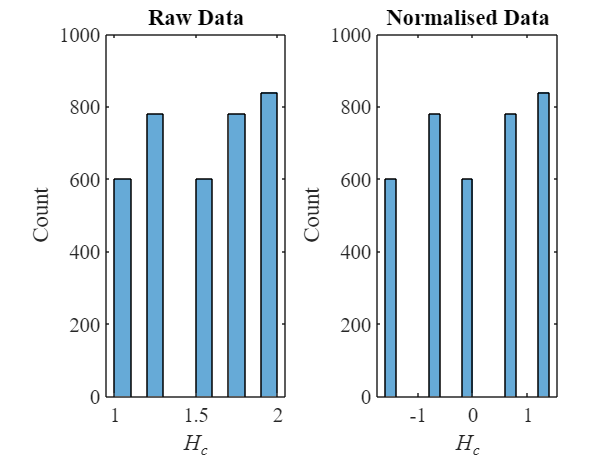

figure(1)
subplot(1,2,1)
histogram(data{:, var});
title("Raw Data")
xlabel(var_names(var))
ylabel('Count')
v=get(1,'currentaxes');
set(v,'fontsize',14,'fontname','Times New Roman')
box on

subplot(1,2,2)
histogram(n_data{:, var});
title("Normalised Data")
xlabel(var_names(var))
ylabel('Count')
v=get(1,'currentaxes');
set(v,'fontsize',14,'fontname','Times New Roman')
box on

## Feature Selection

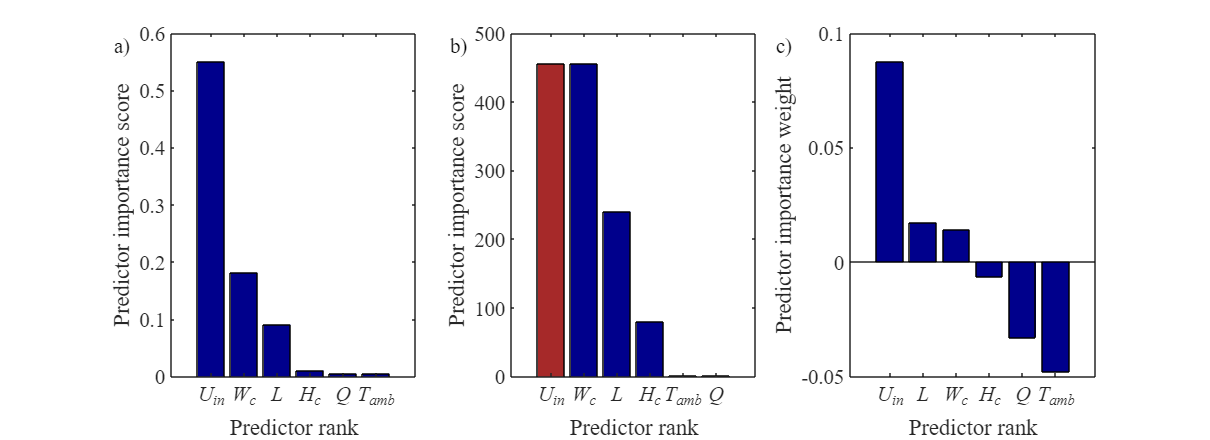

figure(2)
set(gcf, 'Position', [0 0 1100 400]);

% minimum redundancy maximum relevance
[idx,scores] = fsrmrmr(n_data,"PressurePaPressureProbe3");
subplot(1,3,1)
bar(scores(idx), 'FaceColor', blue)
% title("mRMR Algorithm")
xlabel("Predictor rank")
ylabel("Predictor importance score")
xticklabels({'\itU_{in}','\itW_{c}','\itL', '\itH_{c}', '\itQ', '\itT_{amb}'})
v=get(2,'currentaxes');
set(v,'FontSize',14,'FontName','Times New Roman', 'XTickLabelRotation', 0);
box on

% F-tests 
% o/p is -log(p-value)
[idx,scores] = fsrftest(n_data,"PressurePaPressureProbe3");
subplot(1,3,2)
idxInf = find(isinf(scores));
bar(scores(idx), 'FaceColor', blue)
xticklabels({'\itU_{in}','\itW_{c}','\itL', '\itH_{c}', '\itT_{amb}', '\itQ'})
hold on
bar(scores(idx(length(idxInf)+1))*ones(length(idxInf),1), 'FaceColor', red)
hold off
% title("F-tests")
xlabel('Predictor rank')
ylabel('Predictor importance score')
v=get(2,'currentaxes');
set(v,'FontSize',14,'FontName','Times New Roman', 'XTickLabelRotation', 0);
box on

% RReliefF algorithm (using 10 nearest neighbours)
subplot(1,3,3)
[idx,weights] = relieff(n_data{:,1:6}, n_data{:, 7}, 10);
bar(weights(idx), 'FaceColor', blue)
% title("RReliefF Algorithm")
xlabel('Predictor rank')
ylabel('Predictor importance weight')
xticklabels({'\itU_{in}','\itL', '\itW_{c}', '\itH_{c}', '\itQ', '\itT_{amb}'})
v=get(2,'currentaxes');
set(v,'FontSize',14,'FontName','Times New Roman', 'XTickLabelRotation', 0);
box on

annotation('textbox',[0.088 0.8625 0.03 0.0725],'String','a)',...
    'FontSize',14,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');
annotation('textbox',[0.366 0.8625 0.03 0.0725],'String','b)',...
    'FontSize',14,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');
annotation('textbox',[0.635 0.8625 0.03 0.0725],'String','c)',...
    'FontSize',14,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');

## Others

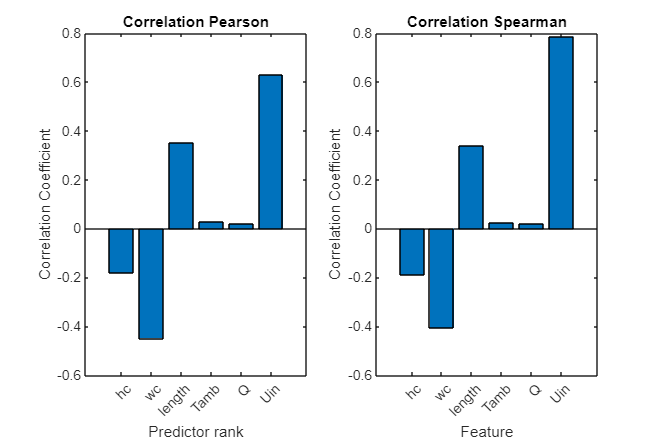

% pearson
figure();
subplot(1,2,1)
set(gcf,'Position',[0 0 600 400])
r = corr(n_data{:,:}, Type="Pearson");
bar(r(7,1:6))
title("Correlation Pearson")
xlabel('Predictor rank')
ylabel('Correlation Coefficient')
xticklabels(strrep(n_data.Properties.VariableNames(),'_','\_'))
xtickangle(45)

% spearman
r = corr(n_data{:,:}, Type="Spearman");
subplot(1,2,2)
bar(r(7,1:6))
title("Correlation Spearman")
xlabel('Feature')
ylabel('Correlation Coefficient')
xticklabels(strrep(n_data.Properties.VariableNames(),'_','\_'))
xtickangle(45)

mdl = fsrnca(n_data{:,1:6}, n_data{:, 7},'Verbose',1,'Lambda',0.5/100);


 o Tuning initial learning rate: NumTuningIterations = 20, TuningSubsetSize = 100

|===============================================|
|    TUNING    | TUNING SUBSET |    LEARNING    |
|     ITER     |   FUN VALUE   |      RATE      |
|===============================================|
|            1 |  1.489621e+01 |   1.000000e-01 |
|            2 |  1.274509e+01 |   5.000000e-02 |
|            3 |  1.274509e+01 |   5.000000e-02 |
|            4 |  1.243359e+01 |   1.000000e-01 |
|            5 |  1.243359e+01 |   1.000000e-01 |
|            6 |  1.243359e+01 |   1.000000e-01 |
|            7 |  1.243359e+01 |   1.000000e-01 |
|            8 |  1.200857e+01 |   5.000000e-02 |
|            9 |  1.200857e+01 |   5.000000e-02 |
|           10 |  1.200857e+01 |   5.000000e-02 |
|           11 |  1.200857e+01 |   5.000000e-02 |
|           12 |  1.200857e+01 |   5.000000e-02 |
|           13 |  1.200857e+01 |   5.000000e-02 |
|           14 |  1.200857e+01 |   5.000000e-02 |
|           15 |

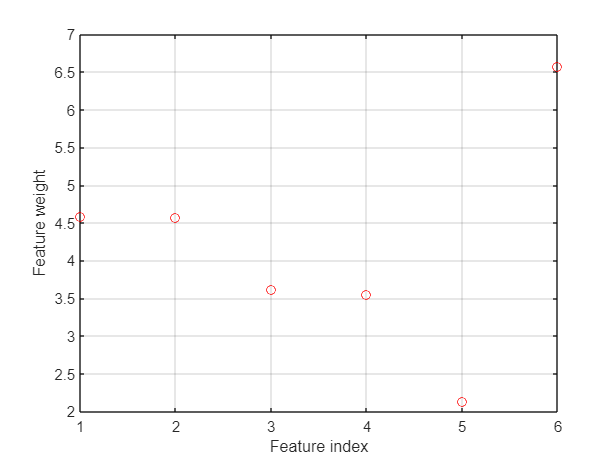

figure()
plot(mdl.FeatureWeights,'ro')
grid on
xlabel('Feature index')
ylabel('Feature weight')